clear all
small_media
%h=figure('Units','inches','Position',[0 0 1.25 0.9])
glucose(1:31)=0.0;
for t=1:31
    varname=genvarname(['media_' int2str((t-1)*100)]);
    glucose(t)=glucose(t)+eval(varname)/1e-4;
end

f=plot(0.05*[0:100:3000]/24,glucose(:),'LineWidth',2,'Color','black')

f =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.2083 0.4167 0.6250 0.8333 1.0417 1.2500 1.4583 1.6667 1.8750 2.0833 2.2917 2.5000 2.7083 2.9167 3.1250 3.3333 3.5417 3.7500 3.9583 4.1667 4.3750 4.5833 4.7917 5 5.2083 5.4167 5.6250 5.8333 6.0417 6.2500]
              YData: [0.0030 0.0030 0.0030 0.0029 0.0029 0.0028 0.0027 0.0026 0.0025 0.0024 0.0023 0.0022 0.0021 0.0020 0.0019 0.0018 0.0017 0.0016 0.0016 0.0015 0.0014 0.0013 0.0013 0.0012 0.0011 0.0011 0.0010 9.6092e-04 9.0916e-04 8.6021e-04 … ]

  Show all properties


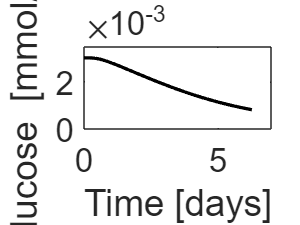

ax =   Axes with properties:

             XLim: [0 7]
             YLim: [0 0.0035]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1894 0.7750 0.7128]
            Units: 'normalized'

  Show all properties


xlim([0,7])
xlabel('Time [days]','FontSize',15)
ylabel('Glucose [mmol/cm^2]','FontSize',15)
ylim([0 3.5e-3])
%xticklabels(gcf,'FontSize',10)
ax=gca;
ax.FontSize=20

saveas(gcf,'glucose.png')